**Time-frequency analysis of power**

**1 Read in trials**

data60: stimuli tagged at 60 Hz (both Target and Distractor)

data67: stimuli tagged at 67 Hz (T & D)

HP filtered at 52 Hz, detrended

**2 Pad data to 8 seconds (by hand because fieldtrip gave me strange results)**

**This is again to avoid losing data**

% pad data to 8 seconds
datapad60 = data60;
datapad67 = data67;
% change time vector
datapad60.time(:) = {-2.5:1/fs:5.5-1/fs};
datapad67.time(:) = {-2.5:1/fs:5.5-1/fs};
padlength = 8*fs;                % total length incl padding

% apply zero padding
% stimuli tagged at 60
for t = 1:length(datapad60.trial)
    pad = zeros(length(data60.label),padlength-size(data60.trial{t},2));
    datapad60.trial{t} = horzcat(datapad60.trial{t},pad);
end
% target tagged at 67
for t = 1:length(datapad67.trial)
    pad = zeros(length(data67.label),padlength-size(data67.trial{t},2));
    datapad67.trial{t} = horzcat(datapad67.trial{t},pad);
end


**3 Sanity: plot diode average**

% plot trigger channel & diode
cfg = [];
ERF60 = ft_timelockanalysis(cfg,datapad60);
ERF67 = ft_timelockanalysis(cfg,datapad67);

misc4 = 'MISC004';
misc5 = 'MISC005';
fig = figure;
plot(ERF60.time,ERF60.avg(strcmp(ERF60.label,misc4),:))
hold on
plot(ERF67.time,ERF67.avg(strcmp(ERF67.label,misc4),:))
xlim([-.2 0.2])
legend('diode 1 60 Hz', 'diode1 67 Hz')



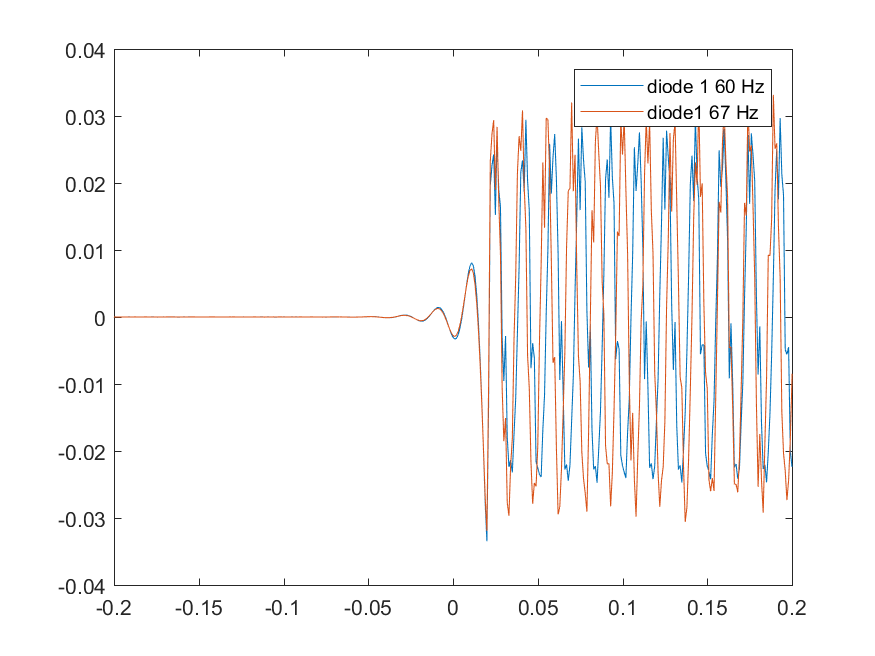

**4 TFR of power of evoked (ERF) and induced flicker response**

winl = 1;            % window length
% frequency analysis
cfg = [];
cfg.method = 'mtmconvol';
cfg.output = 'pow';
cfg.channel = {'MEGGRAD','MISC004','MISC005'};
% cfg.pad = 8;
% cfg.padtype = 'mean';
cfg.foi = 4:1:80;
cfg.taper = 'hanning';
cfg.t_ftimwin = ones(size(cfg.foi)).*winl;
cfg.toi = -1.5:0.05:4;
cfg.keeptrials = 'no';
% induced power
TFR60ind = ft_freqanalysis(cfg,datapad60);
TFR67ind = ft_freqanalysis(cfg,datapad67);

% evoked power
TFR60evo = ft_freqanalysis(cfg,ERF60);
TFR67evo = ft_freqanalysis(cfg,ERF67);


**5 Sanity: TFR diode**

signal is there! Not sure why evoked < induced?

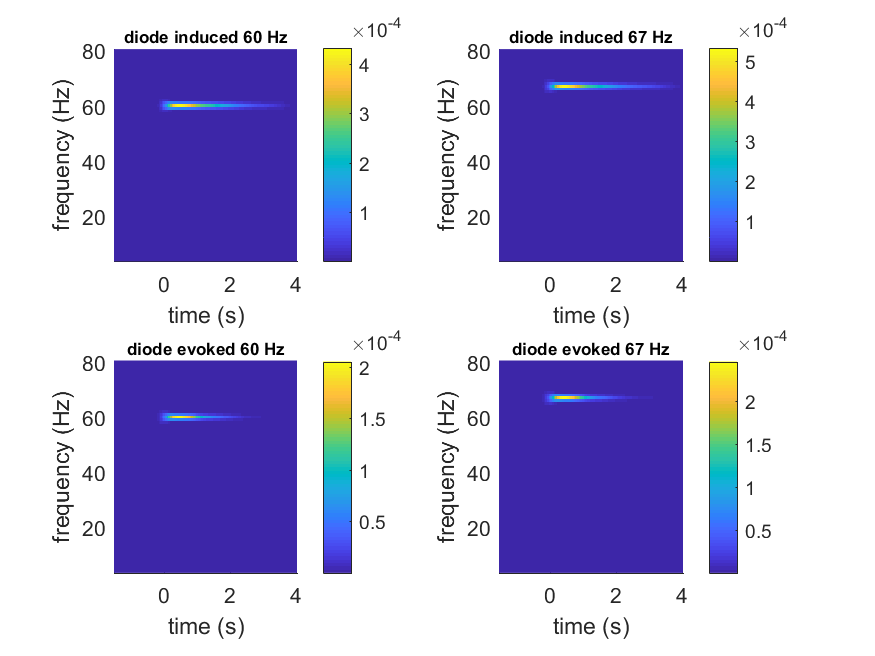

**6 TFR multiplot: no flicker response**

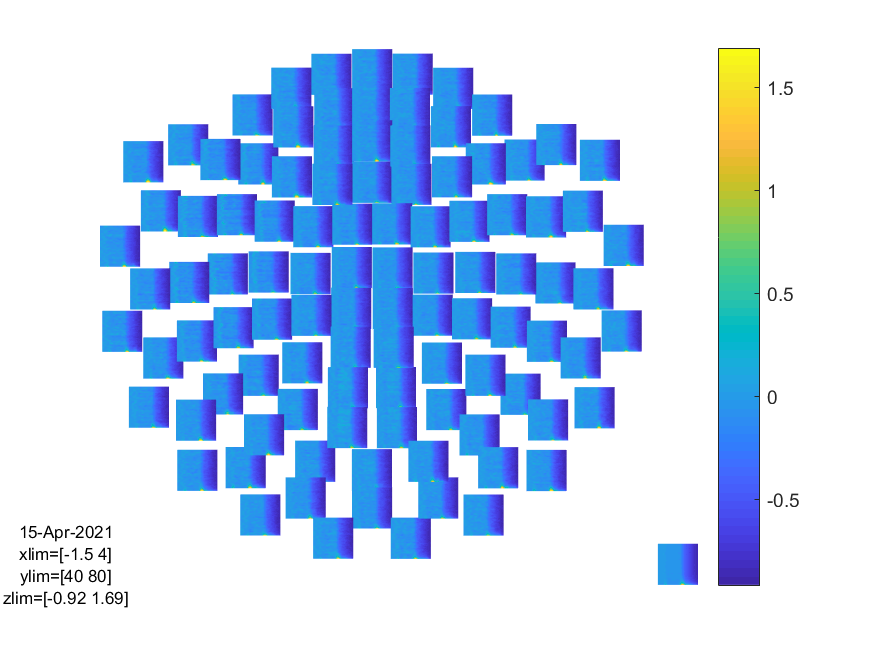

**7 TFR singleplot over SOI: no response**